syms s X1 X2 X3 F

A=[4+4*s+4*s^2 -4*s 0; -4*s 4+8*s+4*s^2 -4; 0 -4 4+2*s+4*s^2]

$$A = \left(\begin{array}{ccc} 4\,s^{2}+4\,s+4 & -4\,s & 0\\ -4\,s & 4\,s^{2}+8\,s+4 & -4\\ 0 & -4 & 4\,s^{2}+2\,s+4 \end{array}\right)$$

X=[X1; X2; X3]

$$X = \left(\begin{array}{c} X_{1}\\ X_{2}\\ X_{3} \end{array}\right)$$

B=[0; F; 0]

$$B = \left(\begin{array}{c} 0\\ F\\ 0 \end{array}\right)$$


X=inv(A)*B

$$X = \begin{array}{l} \left(\begin{array}{c} \frac{F\,\left(2\,s^{2}+s+2\right)}{4\,\left(2\,s^{5}+7\,s^{4}+11\,s^{3}+15\,s^{2}+9\,s+5\right)}\\ \frac{F\,\left(2\,s^{2}+s+2\right)\,\left(s^{2}+s+1\right)}{4\,\sigma_{1}}\\ \frac{F\,\left(s^{2}+s+1\right)}{2\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,s^{6}+7\,s^{5}+11\,s^{4}+15\,s^{3}+9\,s^{2}+5\,s \end{array}$$

pretty(X)

/                    2                      \
|              F (2 s  + s + 2)             |
| ----------------------------------------- |
|     5      4       3       2              |
| (2 s  + 7 s  + 11 s  + 15 s  + 9 s + 5) 4 |
|                                           |
|             2            2                |
|       F (2 s  + s + 2) (s  + s + 1)       |
|       -----------------------------       |
|                    4 #1                   |
|                                           |
|                   2                       |
|               F (s  + s + 1)              |
|               --------------              |
\                    2 #1                   /

where

            6      5       4       3      2
   #1 == 2 s  + 7 s  + 11 s  + 15 s  + 9 s  + 5 s





G=tf([0 0 0 0 1 1 1], [4 14 22 30 18 10 0])

G =
 
                    s^2 + s + 1
  ------------------------------------------------
  4 s^6 + 14 s^5 + 22 s^4 + 30 s^3 + 18 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


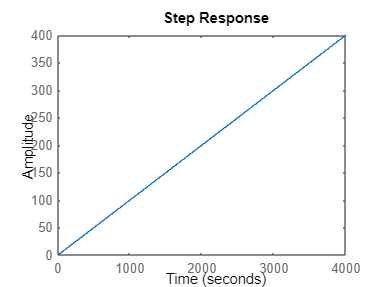

step(G)

Questao 2

syms s I1 I2 Ve

A=[15+(1/(11*s)+1/(6*s)) -3-1/(6*s); -3-1/(6*s) 6+11*s+1/(6*s)]

$$A = \left(\begin{array}{cc} \frac{17}{66\,s}+15 & -\frac{1}{6\,s}-3\\ -\frac{1}{6\,s}-3 & 11\,s+\frac{1}{6\,s}+6 \end{array}\right)$$

X=[I1 ; I2]

$$X = \left(\begin{array}{c} I_{1}\\ I_{2} \end{array}\right)$$

B=[Ve ; 0]

$$B = \left(\begin{array}{c} \mathrm{Ve}\\ 0 \end{array}\right)$$


X=inv(A)*(B)

$$X = \left(\begin{array}{c} \frac{11\,\mathrm{Ve}\,s\,\left(66\,s^{2}+36\,s+1\right)}{10890\,s^{3}+5533\,s^{2}+201\,s+1}\\ \frac{11\,\mathrm{Ve}\,s\,\left(18\,s+1\right)}{10890\,s^{3}+5533\,s^{2}+201\,s+1} \end{array}\right)$$


pretty(X)

/             2                  \
|   Ve s (66 s  + 36 s + 1) 11   |
| ------------------------------ |
|        3         2             |
| 10890 s  + 5533 s  + 201 s + 1 |
|                                |
|       Ve s (18 s + 1) 11       |
| ------------------------------ |
|        3         2             |
\ 10890 s  + 5533 s  + 201 s + 1 /



G=tf([2178 121 0 0], [10890 5533 201 1])

G =
 
         2178 s^3 + 121 s^2
  --------------------------------
  10890 s^3 + 5533 s^2 + 201 s + 1
 
Continuous-time transfer function.
Model Properties


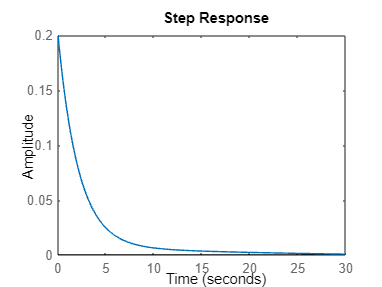

step(G)

Questao 3

syms s I1 I2 Ve

A=[10*s+15 -15; -15 27+4*s]

$$A = \left(\begin{array}{cc} 10\,s+15 & -15\\ -15 & 4\,s+27 \end{array}\right)$$

X=[I1 ; I2]

$$X = \left(\begin{array}{c} I_{1}\\ I_{2} \end{array}\right)$$

B=[Ve ; 0]

$$B = \left(\begin{array}{c} \mathrm{Ve}\\ 0 \end{array}\right)$$


X=inv(A)*(B)

$$X = \left(\begin{array}{c} \frac{\mathrm{Ve}\,\left(4\,s+27\right)}{10\,\left(4\,s^{2}+33\,s+18\right)}\\ \frac{3\,\mathrm{Ve}}{2\,\left(4\,s^{2}+33\,s+18\right)} \end{array}\right)$$

pretty(X)

/     Ve (4 s + 27)     \
| --------------------- |
|     2                 |
| (4 s  + 33 s + 18) 10 |
|                       |
|          3 Ve         |
|  -------------------- |
|      2                |
\  (4 s  + 33 s + 18) 2 /




G=tf([60], [40 330 180])

G =
 
           60
  --------------------
  40 s^2 + 330 s + 180
 
Continuous-time transfer function.
Model Properties


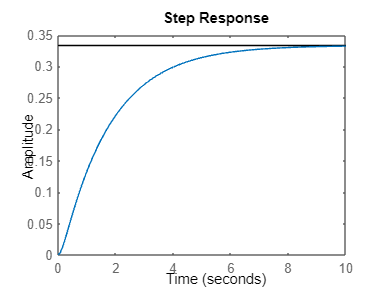

step(G)

Questao 4

syms s X1 X2 F

A=[18+15*s+12*s^2 -5-13*s; -5-13*s 5+25*s+11*s^2]

$$A = \left(\begin{array}{cc} 12\,s^{2}+15\,s+18 & -13\,s-5\\ -13\,s-5 & 11\,s^{2}+25\,s+5 \end{array}\right)$$

X=[X1; X2]

$$X = \left(\begin{array}{c} X_{1}\\ X_{2} \end{array}\right)$$

B=[0; F]

$$B = \left(\begin{array}{c} 0\\ F \end{array}\right)$$


X=inv(A)*B

$$X = \left(\begin{array}{c} \frac{F\,\left(13\,s+5\right)}{132\,s^{4}+465\,s^{3}+464\,s^{2}+395\,s+65}\\ \frac{3\,F\,\left(4\,s^{2}+5\,s+6\right)}{132\,s^{4}+465\,s^{3}+464\,s^{2}+395\,s+65} \end{array}\right)$$

pretty(X)

/              F (13 s + 5)             \
| ------------------------------------- |
|      4        3        2              |
| 132 s  + 465 s  + 464 s  + 395 s + 65 |
|                                       |
|                2                      |
|          F (4 s  + 5 s + 6) 3         |
| ------------------------------------- |
|      4        3        2              |
\ 132 s  + 465 s  + 464 s  + 395 s + 65 /




G=tf([0 0 11 25 5], [132 465 464 395 65])

G =
 
             11 s^2 + 25 s + 5
  ----------------------------------------
  132 s^4 + 465 s^3 + 464 s^2 + 395 s + 65
 
Continuous-time transfer function.
Model Properties


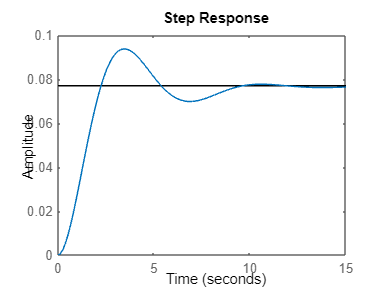

step(G)